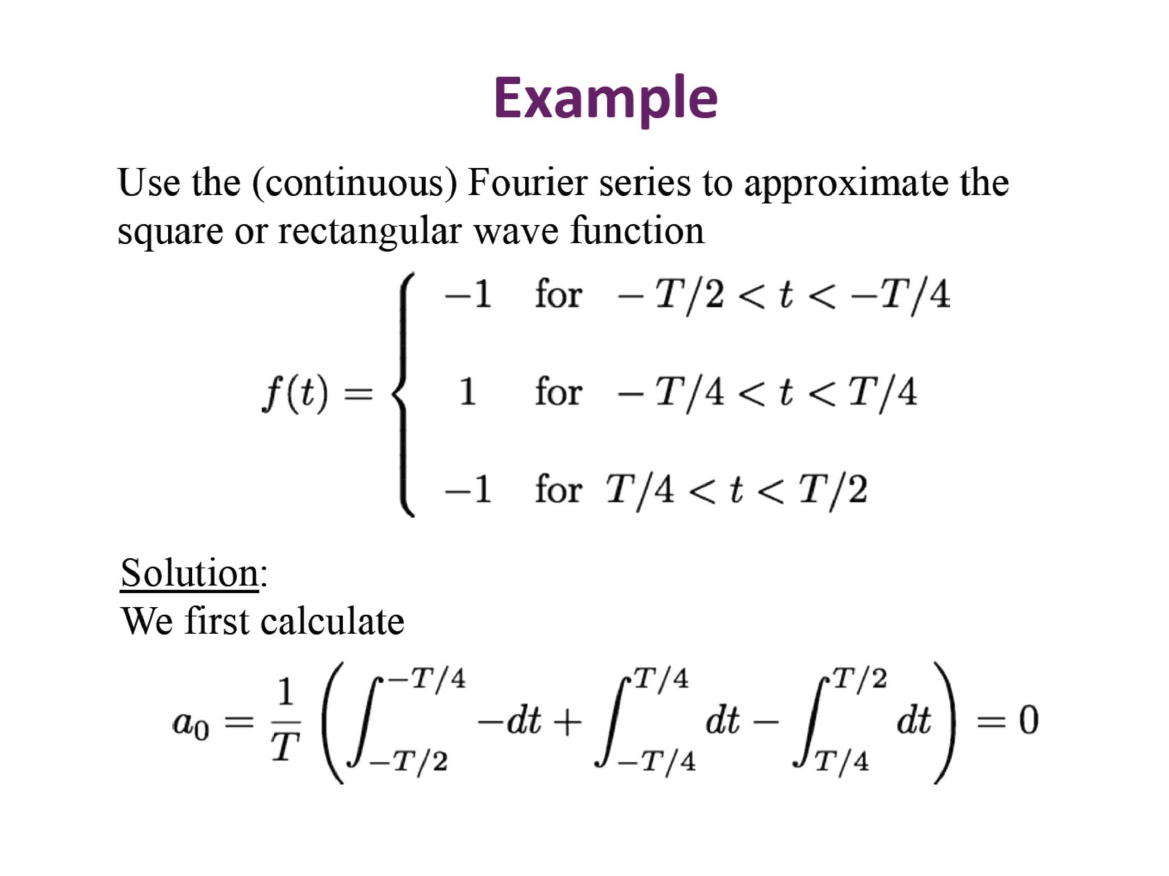

when n is 1

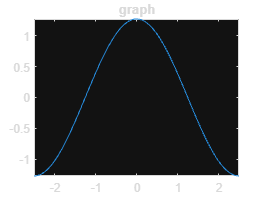

when n is 2

when n is 3

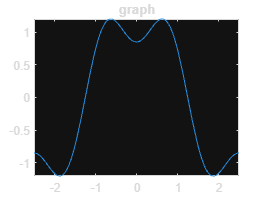

when n is 4

when n is 5

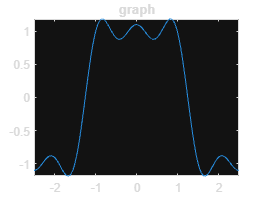

when n is 6

when n is 7

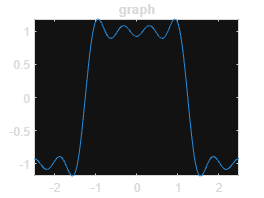

when n is 8

when n is 9

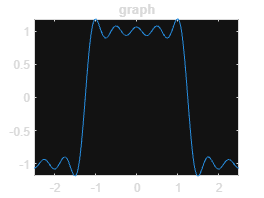

when n is 10

clear
clf
clc

Ts=0.01;
T=5;
syms t y 

%t=-T/2:Ts:T/2-Ts

f1=-1;
f2=1;
f3=-1;


N=10;%number of harmonic 
n=1:N;

a0=(1/T)*(int(f1,t,-T/2,-T/4)+int(f2,t,-T/4,T/4)+int(f3,t,T/4,T/2));
a_n=(2/T)*(int(f1*cos(2*pi*n*t/T),t,-T/2,-T/4)+int(f2*cos(2*pi*n*t/T),t,-T/4,T/4)+int(f3*cos(2*pi*n*t/T),t,T/4,T/2));
b_n=(2/T)*(int(f1*sin(2*pi*n*t/T),t,-T/2,-T/4)+int(f2*sin(2*pi*n*t/T),t,-T/4,T/4)+int(f3*sin(2*pi*n*t/T),t,T/4,T/2));

F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    figure;
    
    fprintf("when n is %d",i)
    fplot(F,[-T/2, T/2])
    title('graph')

end


%************************
fprintf("All of n")

All of n

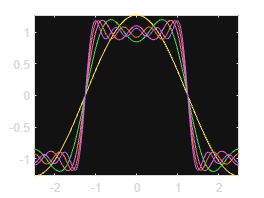

fplot(F,[-T/2, T/2])
F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    
    
    hold on
    fplot(F,[-T/2, T/2])
    hold off
    
end

%*************************
F

$$F = \frac{4\,\cos\left(2\,\pi \,t\right)}{5\,\pi }+\frac{4\,\cos\left(\frac{2\,\pi \,t}{5}\right)}{\pi }-\frac{4\,\cos\left(\frac{6\,\pi \,t}{5}\right)}{3\,\pi }-\frac{4\,\cos\left(\frac{14\,\pi \,t}{5}\right)}{7\,\pi }+\frac{4\,\cos\left(\frac{18\,\pi \,t}{5}\right)}{9\,\pi }$$

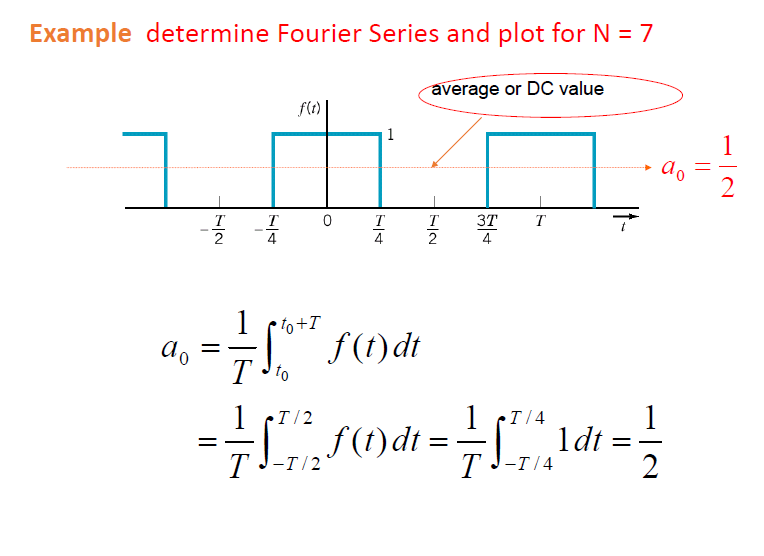

clear
clf
clc

Ts=0.01;
T=5;
syms t y 

%t=-T/2:Ts:T/2-Ts

f1=0;
f2=1;
f3=0;


N=7;%number of harmonic 
n=1:N;

a0=(1/T)*(int(f1,t,-T/2,-T/4)+int(f2,t,-T/4,T/4)+int(f3,t,T/4,T/2))

$$a0 = \frac{1}{2}$$

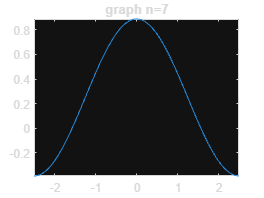

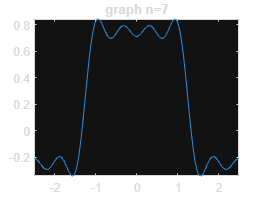

a_n=(2/T)*(int(f1*cos(2*pi*n*t/T),t,-T/2,-T/4)+int(f2*cos(2*pi*n*t/T),t,-T/4,T/4)+int(f3*cos(2*pi*n*t/T),t,T/4,T/2));
b_n=(2/T)*(int(f1*sin(2*pi*n*t/T),t,-T/2,-T/4)+int(f2*sin(2*pi*n*t/T),t,-T/4,T/4)+int(f3*sin(2*pi*n*t/T),t,T/4,T/2));

F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    
    fplot(F,[-T/2, T/2])
    title('graph n=7')
end


%************************
fprintf("n=[1,7]")

n=[1,7]

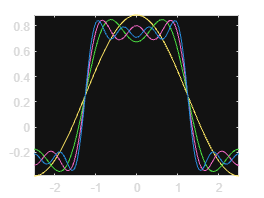

fplot(F,[-T/2, T/2])
F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    
    
    hold on
    fplot(F,[-T/2, T/2])
    hold off
    
end

%*************************
F

$$F = \frac{2\,\cos\left(2\,\pi \,t\right)}{5\,\pi }+\frac{2\,\cos\left(\frac{2\,\pi \,t}{5}\right)}{\pi }-\frac{2\,\cos\left(\frac{6\,\pi \,t}{5}\right)}{3\,\pi }-\frac{2\,\cos\left(\frac{14\,\pi \,t}{5}\right)}{7\,\pi }+\frac{1}{4}$$

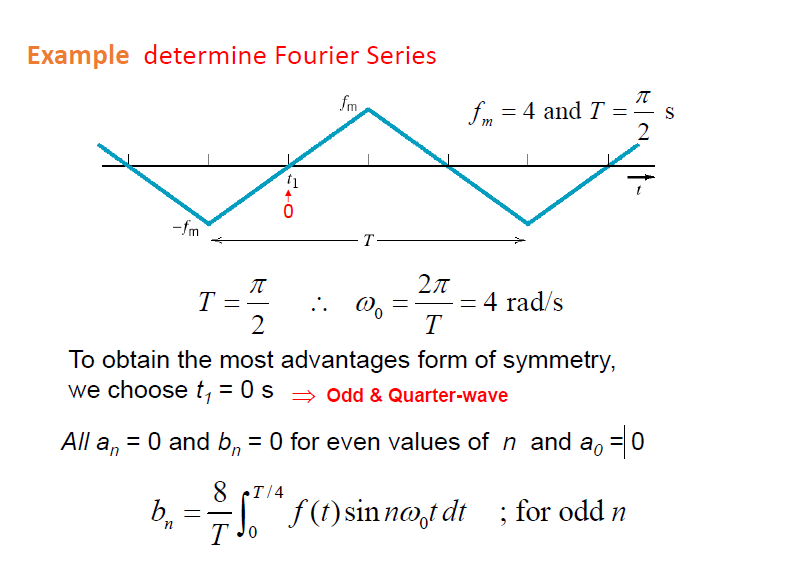

เรากำหนดสมการให้ t1 หรือที่ t=0 อยู่ตรง -fm

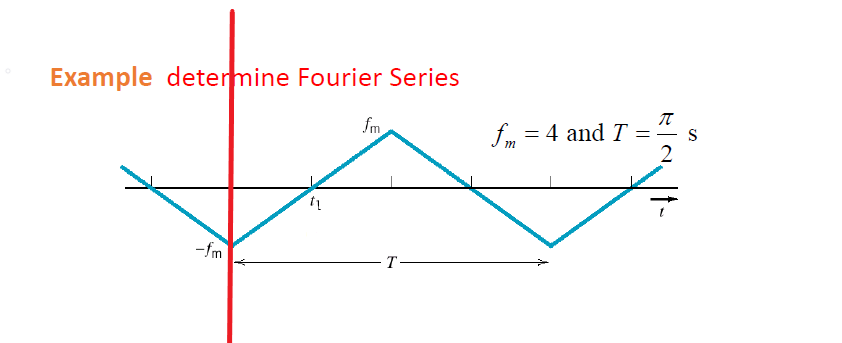

clear
clf
clc

Ts=0.01;
T=pi/2;
fm=4;
w0=2*pi/T;
syms t  

%t=-T/2:Ts:T/2-Ts

ft=abs(32/pi*t)-4

$$ft = \frac{5734161139222659\,\left|t\right|}{562949953421312}-4$$



N=7;%number of harmonic 
n=1:N;

a0=(1/T)*(int(ft,t,-T/2,T/2))

$$a0 = \frac{32880603970571302491146779030281\,\pi^{2}}{81129638414606681695789005144064}-\frac{5734161139222659\,\pi }{4503599627370496}$$

when n is 1

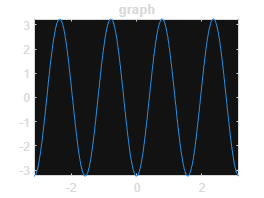

when n is 2

when n is 3

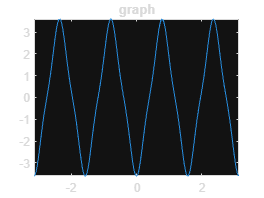

when n is 4

when n is 5

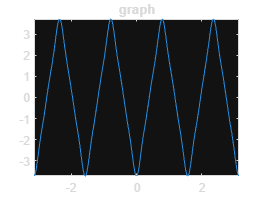

when n is 6

when n is 7

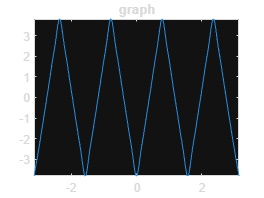

a_n=(2/T)*(int(ft*cos(2*pi*n*t/T),t,-T/2,T/2));
b_n=(2/T)*(int(ft*sin(2*pi*n*t/T),t,-T/2,T/2));

F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    figure;
    
    fprintf("when n is %d",i)
    fplot(F,[-T*2, T*2])
    title('graph')

end


%************************
fprintf("All of n")

All of n

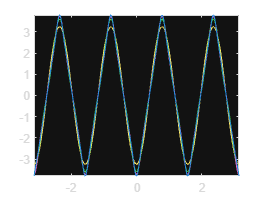

fplot(F,[-T*2, T*2])
F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    
    
    hold on
    fplot(F,[-T*2, T*2])
    hold off
    
end

%*************************
F

$$F = \frac{32880603970571302491146779030281\,\pi^{2}}{162259276829213363391578010288128}-\frac{32880603970571302491146779030281\,\cos\left(4\,t\right)}{10141204801825835211973625643008}-\frac{3653400441174589165682975447809\,\cos\left(12\,t\right)}{10141204801825835211973625643008}-\frac{32880603970571302491146779030281\,\cos\left(20\,t\right)}{253530120045645880299340641075200}-\frac{32880603970571302491146779030281\,\cos\left(28\,t\right)}{496919035289465925386707656507392}-\frac{5734161139222659\,\pi }{9007199254740992}$$

simplify(F)

$$ans = -\frac{32880603970571302491146779030281\,{\cos\left(4\,t\right)}^{7}}{7764359926397905084167307132928}+\frac{295925435735141722420321011272529\,{\cos\left(4\,t\right)}^{5}}{55459713759985036315480765235200}-\frac{113255413676412264136172238882079\,{\cos\left(4\,t\right)}^{3}}{44367771007988029052384612188160}-\frac{208243825146951582443929600525113\,\cos\left(4\,t\right)}{88735542015976058104769224376320}-\frac{5734161139222659\,\pi }{9007199254740992}+\frac{32880603970571302491146779030281\,\pi^{2}}{162259276829213363391578010288128}$$

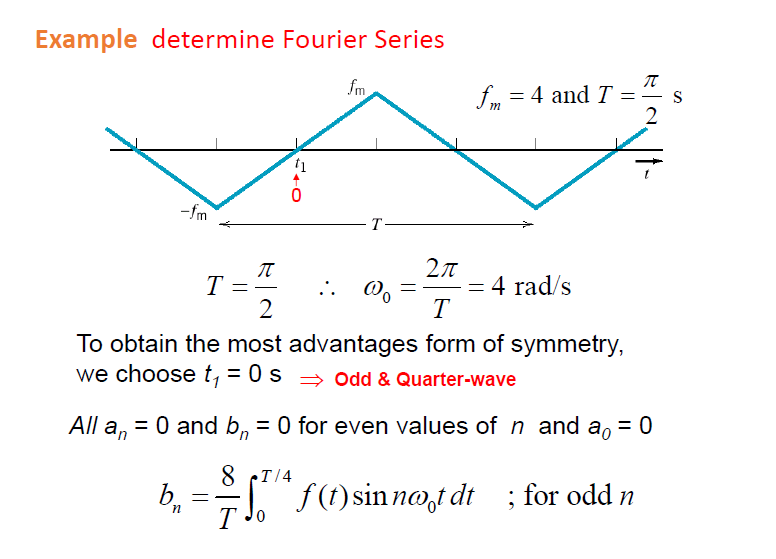

กรณีเราให้ t1=0

clear
clf
clc

Ts=0.01;
T=pi/2;
fm=4;
w0=2*pi/T;
syms t  

%t=-T/2:Ts:T/2-Ts

ft=abs(32/pi*t+4)-4

$$ft = \left|\frac{5734161139222659\,t}{562949953421312}+4\right|-4$$



N=7;%number of harmonic 
n=1:N;

a0=(1/T)*(int(ft,t,-T*3/4,T/4))

$$a0 = \frac{164403019852856512455733895151405\,\pi^{2}}{324518553658426726783156020576256}-\frac{17202483417667977\,\pi }{9007199254740992}+1$$

when n is 1

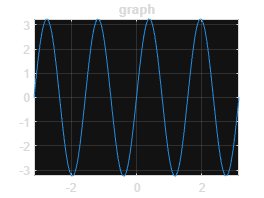

when n is 2

when n is 3

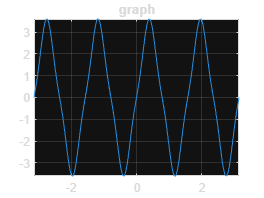

when n is 4

when n is 5

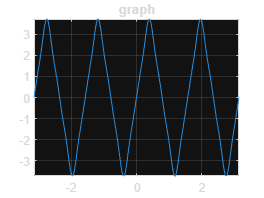

when n is 6

when n is 7

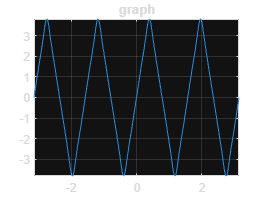

a_n=(2/T)*(int(ft*cos(2*pi*n*t/T),t,-T*3/4,T/4));
b_n=(2/T)*(int(ft*sin(2*pi*n*t/T),t,-T*3/4,T/4));

F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    figure;
    
    fprintf("when n is %d",i)
    fplot(F,[-T*2, T*2])
    grid on
    title('graph')

end


%************************
fprintf("All of n")

All of n

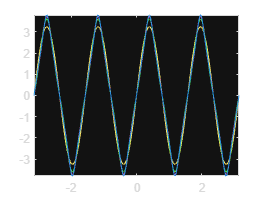

fplot(F,[-T*2, T*2])
F=a0/2;

for i=1:N
    F=F+a_n(i)*cos(i*(2*pi/T)*t)+b_n(i)*sin(i*(2*pi/T)*t);
    
    
    hold on
    fplot(F,[-T*2, T*2])
    hold off
    
end

%*************************
F

simplify(F)

pretty(F)

         /                                     / 9007199254740992 \                                    \            /                                                                           / 9007199254740992 \                    \             /                                                                           / 45035996273704960 \                     \             /                                     / 63050394783186944 \                                                           \                                    /                                     / 45035996273704960 \                                     \             /                                     / 63050394783186944 \                                     \             /                                    / 9007199254740992 \                                    \            /                                     / 18014398509481984 \                                                          \             /         

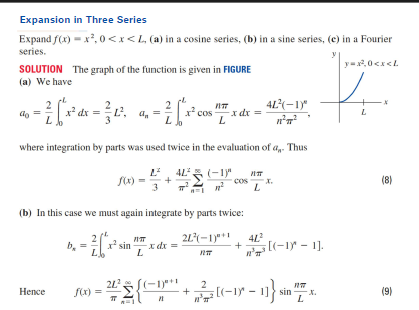

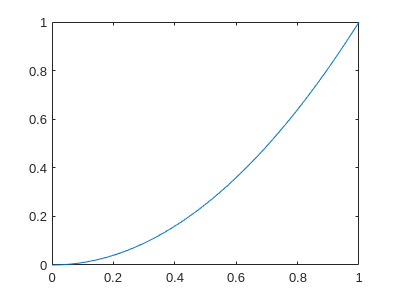

clear
clf
clc

syms x 
L = 1;

ft = x^2;
fplot(ft, [0, L])


N = 50; % number of harmonics 
n = 1:N;

a0 = (2/L) * int(ft, x, 0, L);
a_n = (2/L) * int(ft * cos(pi*n/L*x), x, 0, L);
b_n = (2/L) * int(ft * sin(pi*n/L*x), x, 0, L);

A_n = a0/2;
for i = 1:N
    A_n = A_n + a_n(i) * cos(pi*i/L*x);
end

fprintf("f(x) in a cosine series\n");

f(x) in a cosine series


disp(A_n);

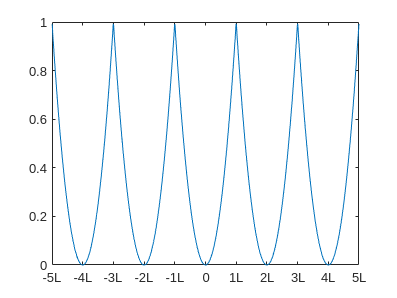


fplot(A_n, [-5*L, 5*L]);
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5] * L);
xticklabels({'-5L','-4L','-3L','-2L','-1L','0','1L','2L','3L','4L','5L'});


%-----------------------------------------

B_n = 0;
for i = 1:N
    B_n = B_n + b_n(i) * sin(pi*i/L*x);
end

fprintf("f(x) in a sine series\n");

f(x) in a sine series


disp(B_n);

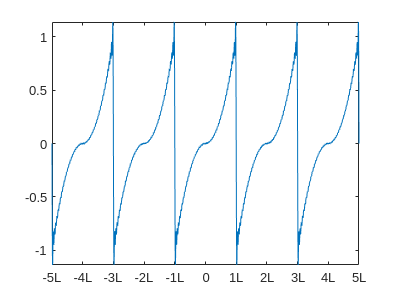


figure;
fplot(B_n, [-5*L, 5*L]);
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5]);
xticklabels({'-5L','-4L','-3L','-2L','-1L','0','1L','2L','3L','4L','5L'});


%-----------------------------------------

F_n = a0/2;
for i = 1:N
    F_n = F_n + a_n(i) * cos(pi*i/L*x) + b_n(i) * sin(pi*i/L*x);
end

fprintf("f(x) in a Fourier series\n");

f(x) in a Fourier series


disp(F_n);

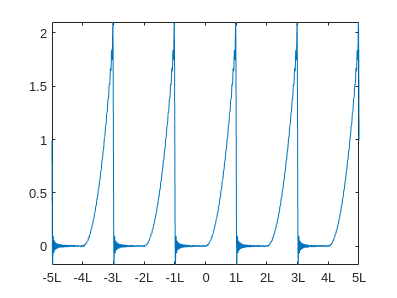


figure;
fplot(F_n, [-5*L, 5*L]);
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5] );
xticklabels({'-5L','-4L','-3L','-2L','-1L','0','1L','2L','3L','4L','5L'});